# **FORRÅR 2016 REEKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

En diskret stokastisk variabel $X$har følgende tæhedsfunktion.

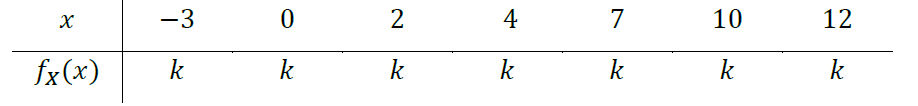

## 1.1 GYLDIG TÆTHEDSFUNKTION

For at bestemme for hvilken værdi af $k$, hvor $f_X \left(x\right)$er en gyldig tæthedsfunktione anvend, at


$$\sum_{i=1}^n f_x \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


syms k

fx = k + k + k + k + k + k + k == 1;

solve(fx, k)

$$ans = \frac{1}{7}$$

For værdien af $k$ lig med $\frac{1}{7}$ er $f_X \left(x\right)$en gyldig tæthedsfunktion.

## 1.2 SKITSERING AF TÆTHEDSFUNKTION

Følgende er en skitsering af tæthedsfunktionen lavet i matlab under antaglese af at k har værdien $\frac{1}{7}$.

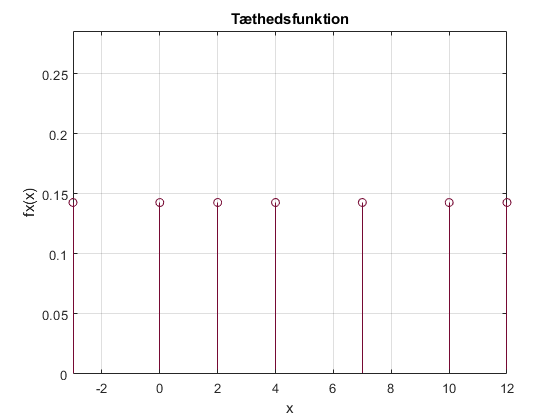

k = 1/7;

X = [-3, 0, 2, 4, 7, 10, 12];
P = [k, k, k, k, k, k, k];

figure(1)
stem(X, P, 'o', 'Color', Color.DeepCleret);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
xlim([-3 12])
ylim([0 k*2])

## 1.3 FORVENTNINGSVÆRDI OG VARIANS

For at bestemme forventningsværdien og variansen ud fra $F_X \left(x\right)$ anvendes at der for forventningsværdien gælder, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

EstimationX

EstimationX = 4.5714

For variansen gælder der, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2

VarianceX = 25.1020

Variansen er dermed bestemt til at være 25.1.

## 1.4 SANDSYNLIGHEDER

For at bestemme $P\left(x\ge 2\right)$samt $P\left(x>2\right)$ anvendes, at arealet for en tæthedsfunktion er lig med 1, hvormed


$$\sum_{i=1}^n f_X \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


Samtidig antages, at $k=\frac{1}{7}$.

fx = @(x) k;

ProbabilityEqualOrAbove = sym(fx(2) + fx(4) + fx(7) + fx(10) + fx(12))

$$ProbabilityEqualOrAbove = \frac{5}{7}$$

Dermed er $P\left(x\ge 2\right)$bestemt til at være $\frac{5}{7}$.

fx = @(x) k;

ProbabilityAbove = sym(fx(4) + fx(7) + fx(10) + fx(12))

$$ProbabilityAbove = \frac{4}{7}$$

Dermed er $P\left(x>2\right)$ bestemt til at være $\frac{4}{7}$.

## 1.5 FORDELINGSFUNKTION

For at bestemme fordelingsfunktionen for $X$anvendes, at 


$$F_x \left(x\right)=\sum_{x_i \le x}^n f_x \left(x_i \right)=P\left(X\le x\right)$$


Hvor det for eksempler af mellemregninger giver, at


$$F_x \left(-3\right)=$$

$$\sum_{x_i \le -3}^n f_x \left(-3\right)=f_x \left(-3\right)=\frac{1}{7}$$



$$F_x \left(0\right)=$$

$$\sum_{x_i \le 0}^n f_x \left(0\right)=f_x \left(-3\right)+f_x \left(0\right)=\frac{2}{7}$$


$F_x \left(2\right)=$$\sum_{x_i \le 2}^n f_x \left(2\right)=f_x \left(-3\right)+f_x \left(0\right)+f_x \left(2\right)=\frac{3}{7}$...

Hvor $k$antages at være $\frac{1}{7}$, hvilket dermed giver, at


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<-3\\
k & -3\le x<0\\
2k & 0\le x<2\\
3k & 2\le x<4\\
4k & 4\le x<7\\
5k & 7\le x<10\\
6k & 10\le x<12\\
7k & x\ge 12
\end{array}\right\rbrack \right\rbrace$$


# **2 STOKASTISKE PROCESSER**

En kontinuer stokastisk process er givet ved


$$X\left(t\right)=w\left(t\right)$$


Hvor $w\left(t\right)$er i.i.d (uafhængig og ens fordelt) og normalfordelt efter $w\left(t\right)\sim N\left(t,1\right)$.

## 2.1 REALISERING

Realiseringen laves ved brug af matlab.

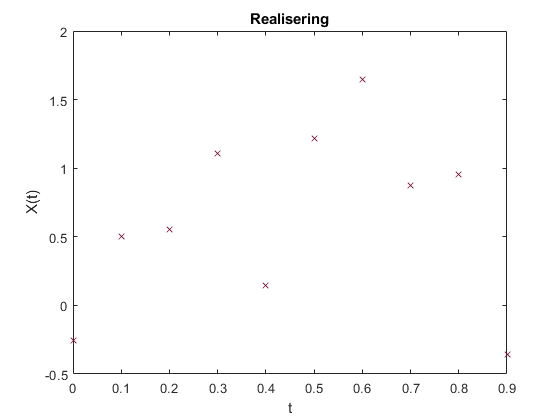

t = 0:0.1:0.9;

mu = t;
sigma = sqrt(1);

Realisation = randn(1, length(t)) + t;

figure(2)
plot(t, Realisation(1, :), 'x', 'Color', Color.DeepCleret);
title('Realisering')
ylabel('X(t)')
xlabel('t')
hold off

## 2.2 ENSEMBLE

For at bestemme middelværdien for ensemble anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack w\left(t\right)\right\rbrack =t$$


Ensemble.MeanValue = t;

Variansen kan bestemmes som


$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left\lbrack w\left(t\right)\right\rbrack =1$$


Ensemble.Variance = sigma^2;

Ensemble

Ensemble = struct with fields:
    MeanValue: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000]
     Variance: 1


Dermed er middelværdien bestemt til at være $t$ og variansen bestemt til at være 1.

## 2.3 TEMPORAL MEAN

Den tidslige middelværdi kan bestemmes som


$$\mu_{X\left(t\right)} \left(t\right)=E\left\lbrack X\left(t\right)\right\rbrack =\int_{-\infty }^{\infty } x\left(t\right)f_{X\left(t\right)} \left(x\left(t\right)\right)\mathrm{dx}\left(t\right)$$


Hvor den forventede tidslige middelværdi i en intervallet kan bestemmes som gennemsnittet i intervallet bestem som følgende.


$$\frac{1}{n}\cdot \int_0^{100} E\left\lbrack X\left(t\right)\right\rbrack \mathrm{dt}$$


t = 0:1:100;

TemporalMeanEstimate = sum(t) / length(t)

TemporalMeanEstimate = 50

## 2.4 PROCESSEN

Da middelværiden er afhængig af tiden er processen ikke WSS. Da processen ikke er WSS kan processen heller ikke være ergodisk.

## 2.5 AUTOKORRELATION

Ligningen til at bestemme autokorrelationen er som følgende


$$R_{x\left(t_1 \right)x\left(t_2 \right)} \left(t_1 =1,t_2 =2\right)=\int_{x\left(t_1 \right)}^{\ldotp } \int_{x\left(t_2 \right)}^{\ldotp } x\left(t_1 \right)x\left(t_2 \right)\cdot f_{X\left(t_1 \right),X\left(t_2 \right)} \left(x\left(t_1 \right),x\left(t_2 \right)\right)\;\mathrm{dx}\left(t_1 \right)\mathrm{dx}\left(t_2 \right)$$


Da $x\left(t_1 \right)$ og $x\left(t_2 \right)$er uafhængige gælder, at


$$R_{x\left(t_1 \right)x\left(t_2 \right)} \left(t_1 =1,t_2 =2\right)=E\left\lbrack x\left(t_1 \right)\right\rbrack \cdot E\left\lbrack x\left(t_2 \right)\right\rbrack$$


Rx = @(x, y) t(x + 1) * t(y + 1);

AutoCorrelationValue = Rx(1, 2)

AutoCorrelationValue = 2

Værdien for autokorrelation er dermed bestemt til at være 2.

# **3 SANDSYNLIGHED**

Et studie viser at hvis et barn på 14 er flyttet mere end én gang på et år, vil barnet med en sansynlighed på 0,06 begå alvorlig kriminalitet indenfor de næste 10 år. For børn, der flyttede én eller færre gange på et år, var sandsynligheden 0,03. 31% af børnene i studiet tilhørte gruppen, der var flyttet mere end en gang.

**A: FLYTTET MERE END EN GANG**

**B: BEGÅR KRIMINALITET**


$$P\left(B|A\right)=0\ldotp 06$$



$$P\left(B|\overline{A} \right)=0\ldotp 03$$



$$P\left(A\right)=0\ldotp 31$$


## 3.1 TOTALE SANDSYNLIGHED

Den totale sandsynlighed for hændelse **B** kan bestemmes ved, at anvende følgende.


$$P\left(B\right)=P\left(B\cap A\right)+P\left(B\cap \bar{A} \right)$$



$$P\left(B\right)=P\left(B\left|A\right.\right)\cdot P\left(A\right)+P\left(B\left|\bar{A} \right.\right)\cdot P\left(\bar{A} \right)$$


BGivenA = 0.06;
BGivenNotA = 0.03;
A = 0.31;

NotA = 1 - A;

B = BGivenA * A + BGivenNotA * NotA

B = 0.0393

Sandsynligheden for hændelse B er dermed bestemt til at være 0.0393 altså 3.93%.

## 3.2 BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for om et barn tilhørte gruppen der havde flyttet mere end en gang, hvis det havde begået kriminalitet anvendes, at


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


AGivenB = (BGivenA * A) / B

AGivenB = 0.4733

Sandsynligheden er dermed bestemt til at være 0.4733 altså 47.33%.

# **4 STATISTIK**

I et studie af tandhvalers forventede levetid, registrerede man dødsalderen på individuelle tandhvaler. Der blev i studiet registreret 10 hvaler, der var døde i fangenskab, og 10 hvaler, der var døde i det fri.

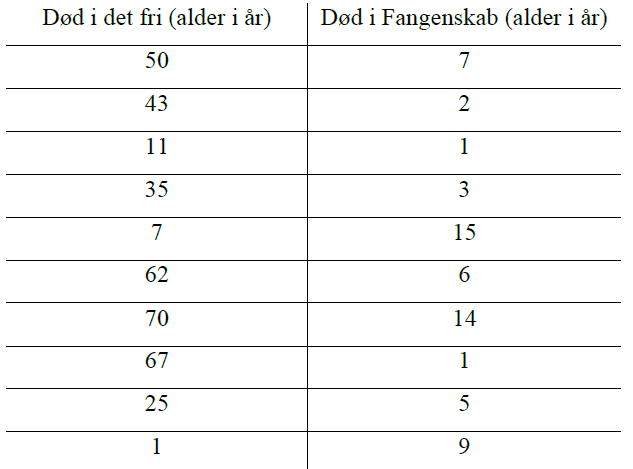

## 4.1 HYPOTESER

Der opstilles en hypotese test for at bestemme om middelværdien af de to grupper er den samme.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


## 4.2 PARRET VS. UPARRET

Da data ikke opfylder samme betingelser, altså eventuele forhold vil det være optimalt at anvende en uparret test. Dette er vurderet på baggrund af dyr i det fri og i fangenskab som ikke har samme vilkår.

## 4.3 ESTIMERING AF MIDDELVÆRDI

Den estimerede middelværdi for de to sample set kan bestemmes som følgende.


$$\mu^ˆ =\frac{1}{n}\sum_{i=1}^n x_i$$


Free.Data = [50, 43, 11, 35, 7, 62, 70, 67, 25, 1];
Captivity.Data = [7, 2, 1, 3, 15, 6, 14, 1, 5, 9];

Free.EstimatedMean = mean(Free.Data)

Free = struct with fields:
             Data: [50 43 11 35 7 62 70 67 25 1]
    EstimatedMean: 37.1000


Captivity.EstimatedMean = mean(Captivity.Data) 

Captivity = struct with fields:
             Data: [7 2 1 3 15 6 14 1 5 9]
    EstimatedMean: 6.3000


De to estimerede middelværdier er dermed bestemt til at være 37.1 samt 6.3.

## 4.4 ESTIMERING AF VARIANS

Den estimerede varians kan bestemmes ud fra de to varianse fra de to sample set givet ved


$$s^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\mu^ˆ \right)}^2$$


Free.Variance = (1/(length(Free.Data) - 1)) * ...
    sum((Free.Data - Free.EstimatedMean).^2);

Captivity.Variance = (1/(length(Captivity.Data) - 1)) * ...
    sum((Captivity.Data - Captivity.EstimatedMean).^2);

Den estimerede varians bestemmes nu som følgende.


$$s^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


Lead = (1 / (length(Free.Data) + length(Captivity.Data) -2));

Back = (length(Free.Data) - 1) * Free.Variance + ... 
    (length(Captivity.Data) - 1) * Captivity.Variance;

PooledVariance = Lead * Back

PooledVariance = 337.1667

Dermed er den estimerede varians bestemt til at være 337.1667.

## 4.5 UPARRET T-TEST

Der anvendes nu en t-test til test af hypotesen. For at undersøge om NULL hypotesen kan afvises med et signifikansniveau på 0.05 anvendes, at


$$t=\frac{\left(\bar{x_1 } -\bar{x_2 } \right)-\delta }{s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}},\;\;p=2\cdot \left(1-t_{\mathrm{cdf}} \left(\left|t\right|,n_1 +n_2 -2\right)\right)$$


t = (Free.EstimatedMean - Captivity.EstimatedMean) / (sqrt(PooledVariance) * ...
    sqrt(1/length(Free.Data) + 1/length(Captivity.Data)));

p = 2 * (1 - tcdf(abs(t), length(Free.Data) + length(Captivity.Data) - 2))

p = 0.0015

NULL hypotesen kan afvises da $p<0\ldotp 05$. 

## 4.6 KONFIDENSINTERVAL

For at finde 95% konfidens intervallet for $\delta$ anvendes, at 


$$\delta_{\pm } =\left(\overline{x_1 } -\overline{x_2 } \right)\pm t_0 \cdot s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}$$


TZero = tinv(0.975, length(Free.Data) + length(Captivity.Data) - 2);

Step = TZero * sqrt(PooledVariance) * sqrt(1/length(Free.Data) + 1/length(Captivity.Data));

Interval.Min = (Free.EstimatedMean - Captivity.EstimatedMean) - Step;
Interval.Max = (Free.EstimatedMean - Captivity.EstimatedMean) + Step;

Interval

Interval = struct with fields:
    Min: 13.5477
    Max: 48.0523


Konfidensintervallet for $\delta$ er dermed bestemt til at være [13.5477; 48.0523].